
clc
clear

1.

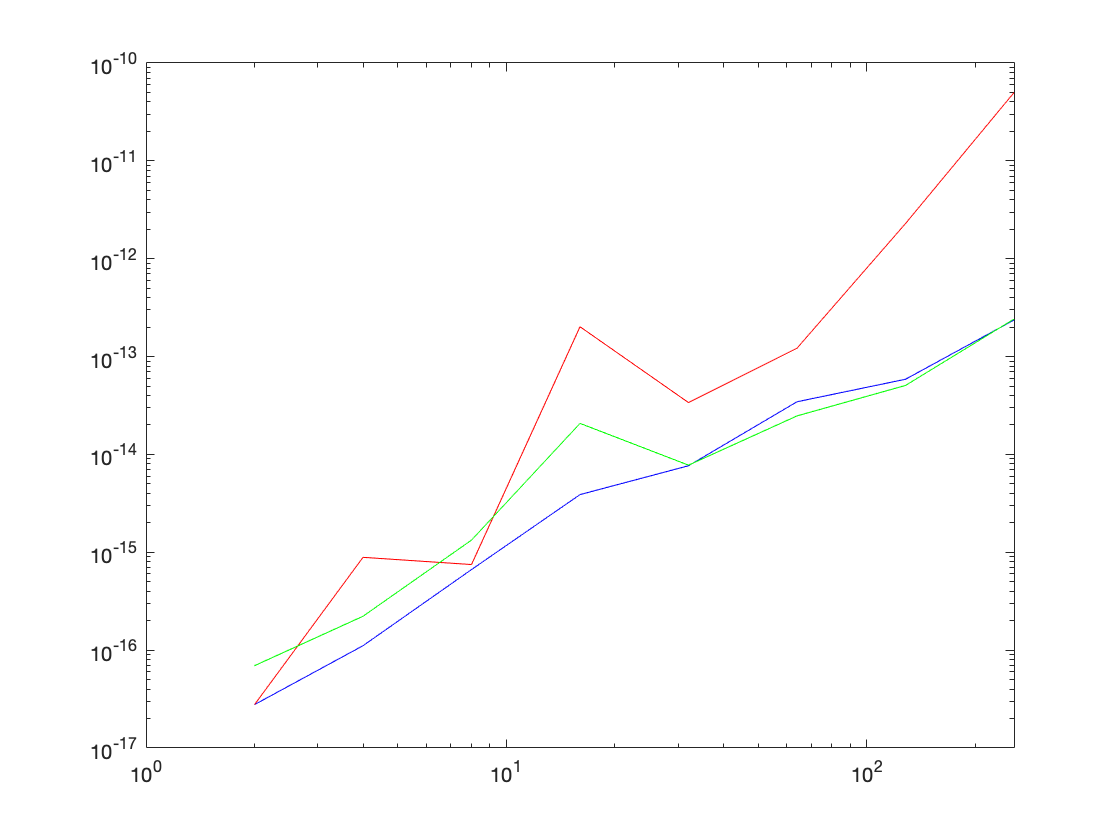

n=2.^(1:8);
rng('default');
for i=1:numel(n)
    h(i)=n(i);
    A=rand(n(i));
    x=rand(n(i),1);
    b=A*x;
    
    error1(i)=norm(x-linsolve(A,b),inf);
    error2(i)=norm(x-my_linsolve(A,b),inf);
    error3(i)=norm(x-pivot_linsolve(A,b),inf);
end
loglog(h,error1,'b',h,error2,'r',h,error3,'g')

function x = my_linsolve(A,b)
    A = [A b];
    n = size(A,1);
    
    for j = 1:n
        for i=j+1:n
            A(i,:)= A(i,:)-A(i,j)/A(j,j)*A(j,:);
            A(i,j)=0;
        end
    end
    for j= n:-1:1
        for i=1:j-1
            A(i,:)=A(i,:)-A(i,j)/A(j,j)*A(j,:);
            A(i,j)=0;
        end
    end
        x=A(1:n,n+1)./diag(A(1:n,1:n));
end 
function x = pivot_linsolve(A,b)
    A = [A b];
    n = size(A,1);
    
    for j = 1:n
        maxr=j;
        maxv=-inf;
        for k=j+1:n
            if abs(A(k,j))>maxv
                maxr=k;
                maxv=abs(A(k,j));
            end
        end
        A([maxr j],:)=A([j maxr],:);
        for i=j+1:n
            A(i,:)=A(i,:)-A(i,j)/A(j,j)*A(j,:);
            A(i,j)=0;
        end
    end
    for j= n:-1:1
        for i=1:j-1
            A(i,:)=A(i,:)-A(i,j)/A(j,j)*A(j,:);
            A(i,j)=0;
        end
    end
        x=A(1:n,n+1)./diag(A(1:n,1:n));
end 
